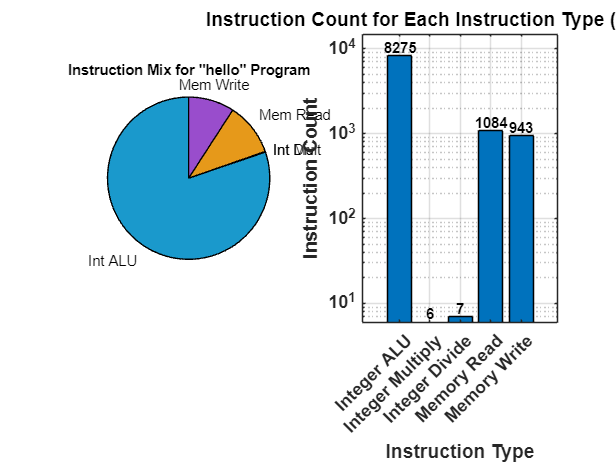

% Instruction mix data
categories = {'Integer ALU', 'Integer Multiply', 'Integer Divide', 'Memory Read', 'Memory Write'};
instruction_counts = [8275, 6, 7, 1084, 943];  % Number of instructions in each category

% Percentages for each category
instruction_percentages = [80.22, 0.06, 0.07, 10.51, 9.14];

% Create pie chart
figure;
subplot(1, 2, 1); % For displaying pie chart and bar chart side by side
p = pie(instruction_percentages, {'Int ALU', 'Int Mult', 'Int Div', 'Mem Read', 'Mem Write'});
title('Instruction Mix for "hello" Program');

% Custom colors for the pie chart
pie_colors = [0.1 0.6 0.8; 0.8 0.4 0.2; 0.4 0.7 0.2; 0.9 0.6 0.1; 0.6 0.3 0.8]; % Custom colors

% Apply custom colors to the pie chart
for i = 1:2:length(p)
    p(i).FaceColor = pie_colors((i+1)/2, :); % Apply color to each slice
end

% Create bar chart with logarithmic scale
subplot(1, 2, 2); % Side-by-side with pie chart
b = bar(instruction_counts);
set(gca, 'XTickLabel', categories);
xlabel('Instruction Type');
ylabel('Instruction Count');
title('Instruction Count for Each Instruction Type (Log Scale)');

% Set Y-axis to logarithmic scale
set(gca, 'YScale', 'log');

% Add percentage labels on top of the bars
for i = 1:length(instruction_percentages)
    text(i, instruction_counts(i), num2str(instruction_counts(i)), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 10, 'FontWeight', 'bold');
end

% Set Y-axis limit to a higher value
ylim([0 max(instruction_counts) * 1.8]);  % Increase the upper limit by 50%

% Customize appearance of bar chart
grid on;
set(gca, 'FontSize', 12, 'FontWeight', 'bold');


% Create a table displaying the instruction counts and percentages
T = table(categories', instruction_counts', instruction_percentages', ...
    'VariableNames', {'Instruction Type', 'Count', 'Percentage'});

% Display the table
disp(T);

      Instruction Type      Count    Percentage
    ____________________    _____    __________

    {'Integer ALU'     }    8275       80.22   
    {'Integer Multiply'}       6        0.06   
    {'Integer Divide'  }       7        0.07   
    {'Memory Read'     }    1084       10.51   
    {'Memory Write'    }     943        9.14   

